# **RS-HL-2: Generate Contact Chart from Given Constellation**

**Hongseok Kim**

**Ver 1.1**

**Last Revised: 6/7/2024**

## Revision History

Ver 1.0: Initial Draft [6/5/2024]

Ver 1.1: Added several functions [6/7/2024]

## Scope

## Interface Specification

clc; clear;
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_1_Constellation_Scinario_Formulation/')

## I. Input information

### I.1 Time Parameter

% Initial Epoch Definition

Year = 2024;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(24);
steptime = 15; % seconds

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);

time_parameters.startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
time_parameters.duration = duration;
time_parameters.steptime = steptime;

scenario = scenario_initalization(time_parameters);



### I.2 Satellite Constellation - Walker Configuration (24 SATs in Single Orbit)

% Intial Orbit Settings

Altitude = 500; % (km)
Eccentricity = 1e-5;
Inclinaton = 97.4022; % (deg)
RAAN = 90;  % (deg)
AOP = 0; % (deg)

% Number of satellites
number_of_SATs = 24;

% Satellite Characteristics - This will entail -1, -2, ... for
% constallation
satellite_name = "RS-1";

% Orbit Propagator
Orbit_Propagator = 'SGP4';


orbit_information.SMA = Altitude*1000 + 6378000;
orbit_information.ecc = Eccentricity;
orbit_information.inc = Inclinaton;
orbit_information.RAAN = RAAN;
orbit_information.AOP = AOP;

% Generate First Stream of Satellites
satellites_orbit_1 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);


% Generate Second Steram of Satellites
RAAN = 105;
orbit_information.RAAN = RAAN;
satellite_name = "RS-2";
satellites_orbit_2 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);

% Merge Satellite Informations
satellites = [satellites_orbit_1, satellites_orbit_2];



### I.4 gs Station Location

gs_info = ["Austin", 30.2672, -97.7431, 15;
           "New York", 40.7128, -74.0060, 10;
           "Los Angeles", 34.0522, -118.4837, 71;
           "Chicago", 41.8781, -87.6298, 181;
           "Houston", 29.7604, -95.3698, 30;
           "Phoenix", 33.4484, -112.0740, 331;
           "Philadelphia", 39.9526, -75.1652, 12;
           "San Antonio", 29.4481, -98.4936, 198;
           "San Diego", 32.7157, -117.1611, 22;
           "Dallas", 32.7767, -96.7970, 137;
           "London", 51.5074, -0.1278, 35;
           "Tokyo", 35.6895, 139.6917, 6;
           "Paris", 48.8566, 2.3522, 35;
           "Moscow", 55.7558, 37.6176, 155;
           "Sydney", -33.8688, 151.2093, 19;
           "Toronto", 43.6511, -79.3830, 76;
           "Berlin", 52.5200, 13.4050, 34;
           "Rome", 41.9028, 12.4964, 17;
           "Seoul", 37.5665, 126.9780, 23;
           "Mumbai", 19.0760, 72.8777, 14;
           "Beijing", 39.9042, 116.4074, 43;
           "Mexico City", 19.4326, -99.1332, 2240;
           "São Paulo", -23.5505, -46.6333, 780;
           "Bangkok", 13.7563, 100.5018, 2;
           "Istanbul", 41.0082, 28.9784, 39;
           "Cairo", 30.0444, 31.2357, 23;
           "Dubai", 25.2769, 55.2963, 4;
           "Singapore", 1.3521, 103.8198, 15;
           "Hong Kong", 22.3193, 114.1694, 39;
           "Sydney", -33.8688, 151.2093, 19];



gs = groundStation(scenario,"Name",gs_info(:,1), ...
                        "Latitude",str2double(gs_info(:,2)), ...
                        "Longitude", str2double(gs_info(:,3)), ...
                        "Altitude", str2double(gs_info(:,4)), ...
                        "MinElevationAngle", 15);


## II. GS to Satellite Access Information Generation

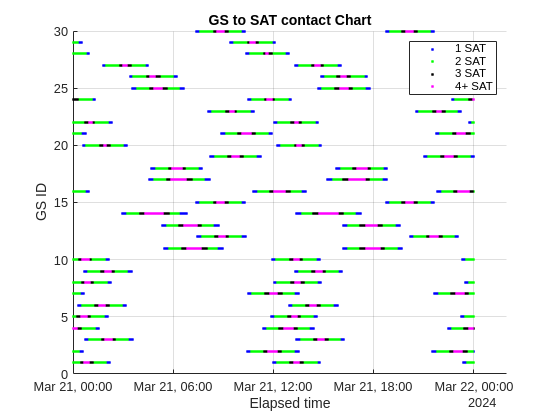


[time_vector, ...
  gs_to_sat_access_table, ...
  gs_to_sat_access_matrix, ...
  gs_to_sat_access_info, ...
  contact_1_sat, ...
  contact_2_sat, ...
  contact_3_sat, ...
  contact_4_plus_sat] = gs_to_sat_access_info_generation(scenario,satellites,gs);


figure;
scatter(scenario.StartTime + seconds(contact_1_sat(:,1))*15,contact_1_sat(:,2),'.','b')
hold on
scatter(scenario.StartTime + seconds(contact_2_sat(:,1))*15,contact_2_sat(:,2),'.','g')
scatter(scenario.StartTime + seconds(contact_3_sat(:,1))*15,contact_3_sat(:,2),'.','k')
scatter(scenario.StartTime + seconds(contact_4_plus_sat(:,1))*15,contact_4_plus_sat(:,2),'.','m')
hold off
title('GS to SAT contact Chart')
xlabel('Elapsed time')
ylabel('GS ID')
legend('1 SAT', '2 SAT', '3 SAT', '4+ SAT')
grid on

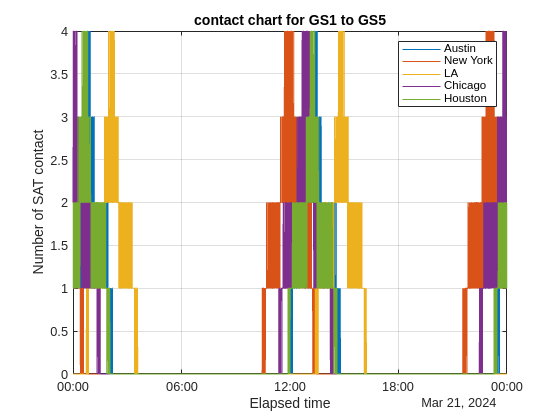


figure;
plot(time_vector,gs_to_sat_access_matrix(1,:))
hold on
plot(time_vector,gs_to_sat_access_matrix(2,:))
plot(time_vector,gs_to_sat_access_matrix(3,:))
plot(time_vector,gs_to_sat_access_matrix(4,:))
plot(time_vector,gs_to_sat_access_matrix(5,:))
hold off
title('contact chart for GS1 to GS5')
xlabel('Elapsed time')
ylabel('Number of SAT contact')
legend('Austin', 'New York', 'LA', 'Chicago', 'Houston')
grid on

## III. Satellite to gs Acces Information Generation

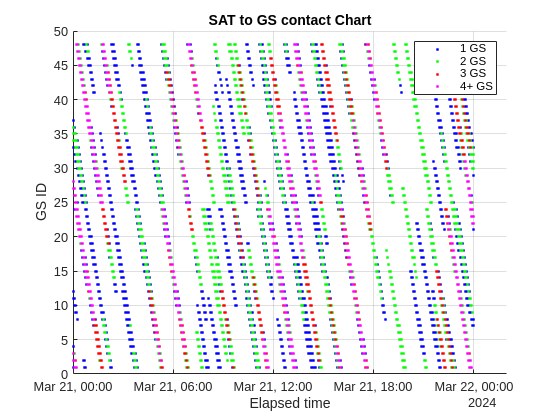

[time_vector, ...
 sat_to_gs_access_table, ...
 sat_to_gs_access_matrix, ...
 sat_to_gs_access_info, ...
 contact_1_gs, ...
 contact_2_gs, ...
 contact_3_gs, ...
 contact_4_plus_gs] = sat_to_gs_access_info_generation(scenario,satellites,gs);



figure;
scatter(scenario.StartTime + seconds(contact_1_gs(:,1))*15,contact_1_gs(:,2),'.','b')
hold on
scatter(scenario.StartTime + seconds(contact_2_gs(:,1))*15,contact_2_gs(:,2),'.','g')
scatter(scenario.StartTime + seconds(contact_3_gs(:,1))*15,contact_3_gs(:,2),'.','r')
scatter(scenario.StartTime + seconds(contact_4_plus_gs(:,1))*15,contact_4_plus_gs(:,2),'.','m')
hold off
grid on
title('SAT to GS contact Chart')
xlabel('Elapsed time')
ylabel('GS ID')
legend('1 GS', '2 GS', '3 GS', '4+ GS')
grid on

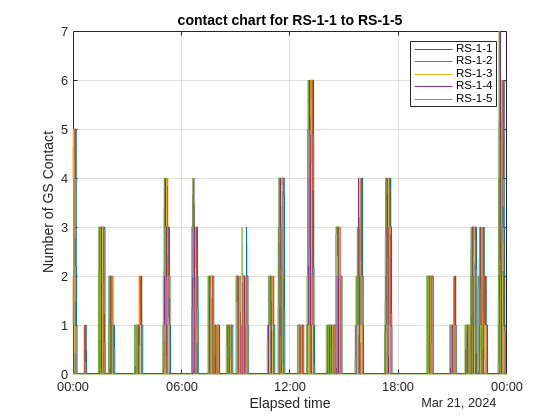



figure;
plot(time_vector,sat_to_gs_access_matrix(1,:))
hold on
plot(time_vector,sat_to_gs_access_matrix(2,:))
plot(time_vector,sat_to_gs_access_matrix(3,:))
plot(time_vector,sat_to_gs_access_matrix(4,:))
plot(time_vector,sat_to_gs_access_matrix(5,:))
hold off
title('contact chart for RS-1-1 to RS-1-5')
xlabel('Elapsed time')
ylabel('Number of GS Contact')
legend('RS-1-1', 'RS-1-2', 'RS-1-3', 'RS-1-4', 'RS-1-5')
grid on

## IV. 3D Data Visualization

figure;


% play(scenario)

## V. Data Analysis